Tutorial 4.3 Computational Neuroscience Jacob Smith

[https://www.mathworks.com/help/signal/ref/findpeaks.html](https://www.mathworks.com/help/signal/ref/findpeaks.html)

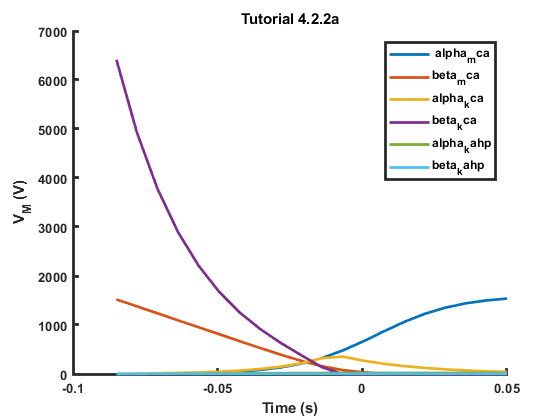

clear;
hold on;
%4.3.2
V_M=spaceFromEnds(-.085,.05,20);
M_CA=spaceFromEnds(0,2e-3,20);
graphTitle="Tutorial 4.2.2a";
[ alpha_mca, beta_mca, alpha_kca, beta_kca, alpha_kahp, beta_kahp ] =PR_dend_gating(V_M,M_CA);
matrix=loadTable(alpha_mca, beta_mca, alpha_kca, beta_kca, alpha_kahp, beta_kahp);
names=[" alpha_mca", "beta_mca", "alpha_kca", "beta_kca" , "alpha_kahp", "beta_kahp"];
plotFigureTable(matrix,V_M,names,"Time (s)","V_M (V)",graphTitle);

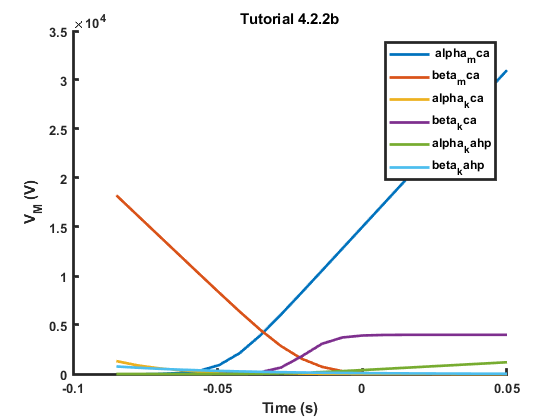


graphTitle="Tutorial 4.2.2b";
figure("Name",graphTitle);
[  alpha_m, beta_m, alpha_h, beta_h , alpha_n, beta_n ] =PR_soma_gating(V_M);
matrix=loadTable(alpha_m, beta_m, alpha_h, beta_h , alpha_n, beta_n );
plotFigureTable(matrix,V_M,names,"Time (s)","V_M (V)",graphTitle);

%4.3.3
%PREulerFinal is one of Paul miller's provided programs, which I turn into
%a function
clear;
graphTitle="Spiking Tutorial 4.2.3";
figure("Name",graphTitle);
%this line of code will reproduce the original graph
%[time,VS,VD]=pREulerFinal(50e-9,5e6,2e-6);
%this line of code is the paremters required in the tutorial
[time,VS,VD]=pREulerFinal(5e-9,0.25e7,10e-6);
graph2Plots(time,VS,VD,graphTitle,"V_S (volts)","V_M (volts)","Time (seconds)");

Not enough input arguments.

Error in graph2PlotsGeneral (line 7)
subplot(numRows,numCols,plotNum);

Error in graph2Plots (line 7)
graph2PlotsGeneral(t,Y1,Y2,graphTitle,y1Title,y2Title,xTitle,2,1,1);



%4.3.4
graphTitle="Spiking Tutorial 4.2.4";
[~,somaticLocs]=findpeaks(VS);
somaticPeaks=indexToBoolean(time,somaticLocs);
[~,dendriteLocs]=findpeaks(VD);
dendritePeaks=indexToBoolean(time,dendriteLocs);
graph2Plots(time,somaticPeaks,dendritePeaks,graphTitle,"V_S (volts)","V_M (volts)","Time (seconds)");


%4.3.4
%This will automatically scale gLinks with as many plots as desirable
graphManyPlots4(10,0,100e-9);


